# **Circuitos Electricos II**

**Roberto Sanchez Figueroa    **

**brrsanchezfi@unal.edu.co**

# **Soluciones propuestas para los ejercicios del taller 10**

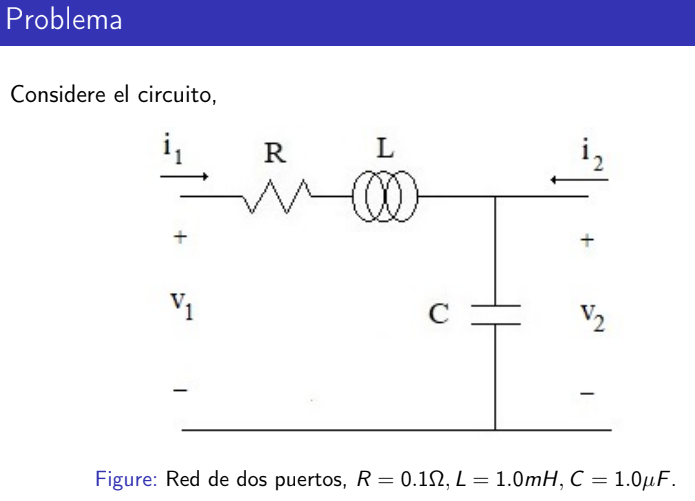

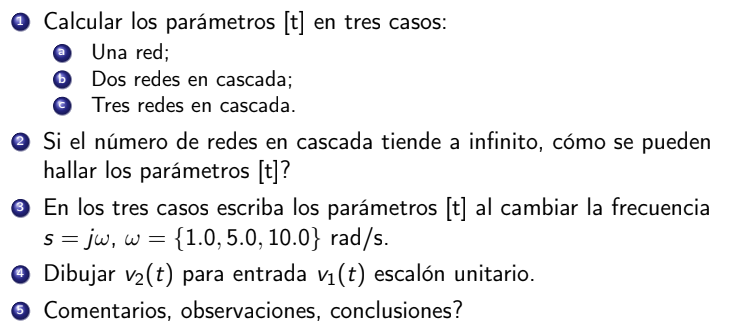

## 1.  Parametros [t]

Red en una cascada

syms L R C s
c = 1e-6;
r = 0.1;
l = 1e-3;

t = [1+(L*s+R)*(C*s) (L*s+R);
    (C*s) 1];

t = subs(t,[L R C],[l r c])

$$t = \left(\begin{array}{cc} 1.0000e-06\,s\,\left(0.0010\,s+0.1000\right)+1 & 0.0010\,s+0.1000\\ 1.0000e-06\,s & 1 \end{array}\right)$$

Dos redes en cascada $t^2$

t_2 = simplify(t*t)

$$t\_2 = \left(\begin{array}{cc} 1.0000e-06\,s\,\left(0.0010\,s+0.1000\right)+{\left(1.0000e-06\,s\,\left(0.0010\,s+0.1000\right)+1\right)}^{2} & 1.0000e-12\,s^{3}+2.0000e-10\,s^{2}+0.0020\,s+0.2000\\ 1.0000e-15\,s\,\left(s^{2}+100\,s+2.0000e+09\right) & 1.0000e-06\,s\,\left(0.0010\,s+0.1000\right)+1 \end{array}\right)$$

Tes redes en cascada $t^3$

t_3 = simplify(t_2*t)

$$t\_3 = \begin{array}{l} \left(\begin{array}{cc} \left(\sigma_{1}+1\right)\,\left(\sigma_{1}+{\left(\sigma_{1}+1\right)}^{2}\right)+1.0000e-06\,s\,\left(1.0000e-12\,s^{3}+2.0000e-10\,s^{2}+0.0020\,s+0.2000\right) & 1.0000e-21\,s^{5}+3.0000e-19\,s^{4}+4.0000e-12\,s^{3}+8.0000e-10\,s^{2}+0.0030\,s+0.3000\\ 1.0000e-24\,s\,\left(s^{4}+200\,s^{3}+4.0000e+09\,s^{2}+4.0000e+11\,s+3.0000e+18\right) & \sigma_{1}+1.0000e-15\,s\,\left(0.0010\,s+0.1000\right)\,\left(s^{2}+100\,s+2.0000e+09\right)+1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1.0000e-06\,s\,\left(0.0010\,s+0.1000\right) \end{array}$$

## 2. t^n

https://ocw.ehu.eus/pluginfile.php/40253/mod_resource/content/1/fundamen_mate/contenidos/ejercicios/ejercicios-resueltos/potencias-de-matrices-cuadradas.pdf

## 3.parametros t al cambiar la frecuencia {1, 0.5, 10}

### t^1

para $\omega =1$

t_1_1 = subs(t,s,1j) 

$$t\_1\_1 = \left(\begin{array}{cc} 1.000+1.0000e-07\,\mathrm{i} & 0.1000+0.0010\,\mathrm{i}\\ 1.0000e-06\,\mathrm{i} & 1 \end{array}\right)$$

para $\omega =0\ldotp 5$

t_1_05 = subs(t,s,0.5j) 

$$t\_1\_05 = \left(\begin{array}{cc} 1.000+5.0000e-08\,\mathrm{i} & 0.1000+5.0000e-04\,\mathrm{i}\\ 5.0000e-07\,\mathrm{i} & 1 \end{array}\right)$$

para $\omega =10$

t_1_10 = subs(t,s,10j) 

$$t\_1\_10 = \left(\begin{array}{cc} 1.000+1.0000e-06\,\mathrm{i} & 0.1000+0.0100\,\mathrm{i}\\ 1.0000e-05\,\mathrm{i} & 1 \end{array}\right)$$

### t^2

t_2_1 = subs(t_2,s,1j) 

$$t\_2\_1 = \left(\begin{array}{cc} 1.000+3.0000e-07\,\mathrm{i} & 0.2000+0.0020\,\mathrm{i}\\ -1.0000e-13+2.0000e-06\,\mathrm{i} & 1.000+1.0000e-07\,\mathrm{i} \end{array}\right)$$

para $\omega =0\ldotp 5$

t_2_05 = subs(t_2,s,0.5j) 

$$t\_2\_05 = \left(\begin{array}{cc} 1.000+1.5000e-07\,\mathrm{i} & 0.2000+0.0010\,\mathrm{i}\\ -2.5000e-14+1.0000e-06\,\mathrm{i} & 1.000+5.0000e-08\,\mathrm{i} \end{array}\right)$$

para $\omega =10$

t_2_10 = subs(t_2,s,10j) 

$$t\_2\_10 = \left(\begin{array}{cc} 1.000+3.0000e-06\,\mathrm{i} & 0.2000+0.0200\,\mathrm{i}\\ -1.0000e-11+2.0000e-05\,\mathrm{i} & 1.000+1.0000e-06\,\mathrm{i} \end{array}\right)$$

### t^3

t_3_1 = subs(t_3,s,1j) 

$$t\_3\_1 = \left(\begin{array}{cc} 1.000+6.0000e-07\,\mathrm{i} & 0.3000+0.0030\,\mathrm{i}\\ -4.0000e-13+3.0000e-06\,\mathrm{i} & 1.000+3.0000e-07\,\mathrm{i} \end{array}\right)$$

para $\omega =0\ldotp 5$

t_3_05 = subs(t_3,s,0.5j) 

$$t\_3\_05 = \left(\begin{array}{cc} 1.000+3.0000e-07\,\mathrm{i} & 0.3000+0.0015\,\mathrm{i}\\ -1.0000e-13+1.5000e-06\,\mathrm{i} & 1.000+1.5000e-07\,\mathrm{i} \end{array}\right)$$

para $\omega =10$

t_3_10 = subs(t_3,s,10j) 

$$t\_3\_10 = \left(\begin{array}{cc} 1.000+6.0000e-06\,\mathrm{i} & 0.3000+0.0300\,\mathrm{i}\\ -4.0000e-11+3.0000e-05\,\mathrm{i} & 1.000+3.0000e-06\,\mathrm{i} \end{array}\right)$$

## 4. respuesta al escalon

### Funcion de transferencia

t_s = (1/(C*s))/(R+L*s+(1/(C*s)))

$$t\_s = \frac{1}{C\,s\,\left(R+L\,s+\frac{1}{C\,s}\right)}$$

t_s = subs(t_s,[L R C],[l r c])

$$t\_s = \frac{1000000}{s\,\left(0.0010\,s+\frac{1000000}{s}+0.1000\right)}$$

t_s = sym2tf( t_s, 0)

t_s =
 
         1e09
  ------------------
  s^2 + 100 s + 1e09
 
Continuous-time transfer function.



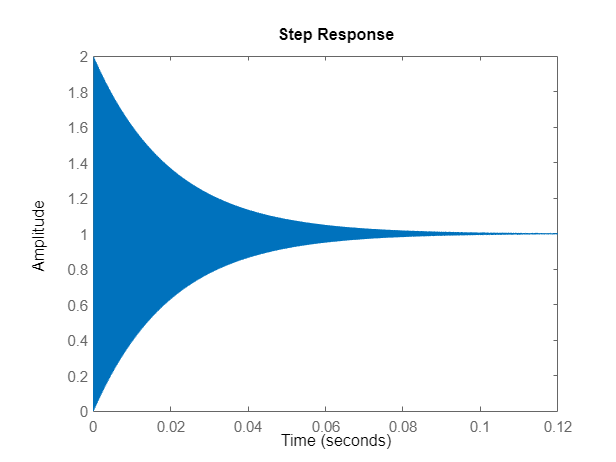

step(t_s)

### Simulacion

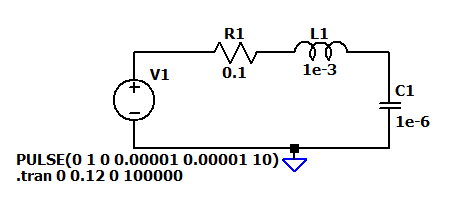

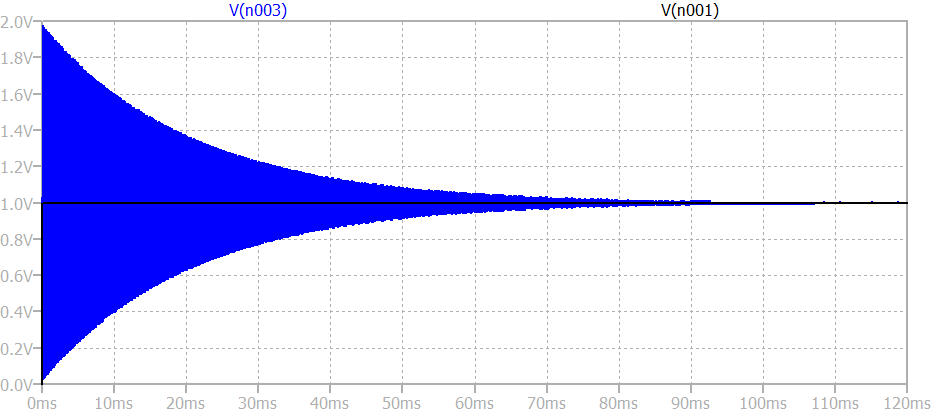

## 5. Comentarios y conclusiones

### Comentarios

- la implementacion de metodos para solucionar problemas matriciales es importante en la computacion, dicho concepto se conoce como complejidad computacional

### Conclusiones

- los parametros de ganacia en un sistema son dependientes tanto del numero de cascadas presentes en el sistema como en la frecuencia aplicada al sistema 

function t_sym = tf2sym(H) 
       [num,den] = tfdata(H);
       syms s;
       t_sym = simplify(poly2sym(cell2mat(num),s)/poly2sym(cell2mat(den),s));
end

function [ tfobj ] = sym2tf( symobj, Ts) %pasa de sym a tf    Ts es el samplin, para continuas dejar en 0
    % SYM2TF convert symbolic math rationals to transfer function
    
    if isnumeric(symobj)
        tfobj=symobj;
        return;
    end
    
    [n,d]=numden(symobj);
    num=sym2poly(n);
    den=sym2poly(d);
    
    if nargin==1
        tfobj=tf(num,den);
    else
        tfobj=tf(num,den,Ts);
    end
end